
clear; close all; clc;

## Initialization:

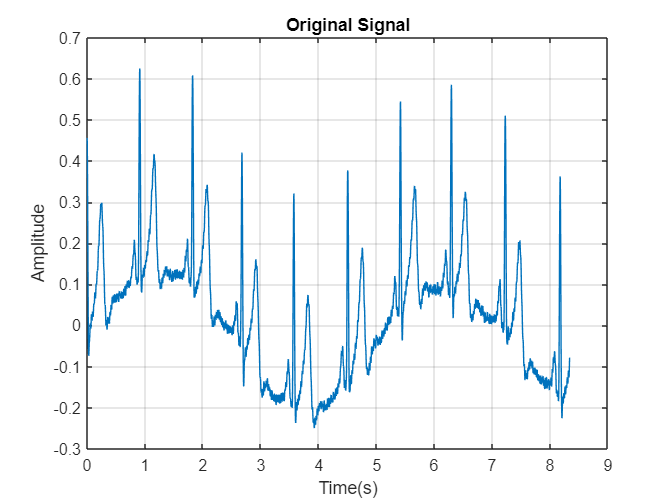


Data = load("Exercise_ecg.mat");
Signal_Original = Data.ecg;



fs = 500; % 500Hz
ts = 1/fs;


T_record = length(Signal_Original)/fs;

t =  0:ts:T_record-ts;


figure();
plot(t,Signal_Original);
grid on
title("Original Signal");
xlabel("Time(s)")
ylabel("Amplitude")

## ZOOMING IN

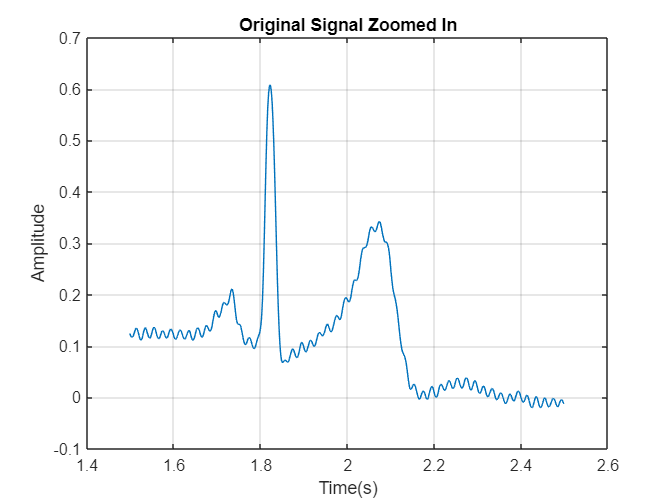


% Choose from 1.5 s to 2.5 s to see a single period of ECG:
index_period_1 = 1.5*fs:2.5*fs ;

figure();
plot(t(index_period_1),Signal_Original(index_period_1));
grid on
title("Original Signal Zoomed In");
xlabel("Time(s)")
ylabel("Amplitude")

## Filter under 0.5Hz

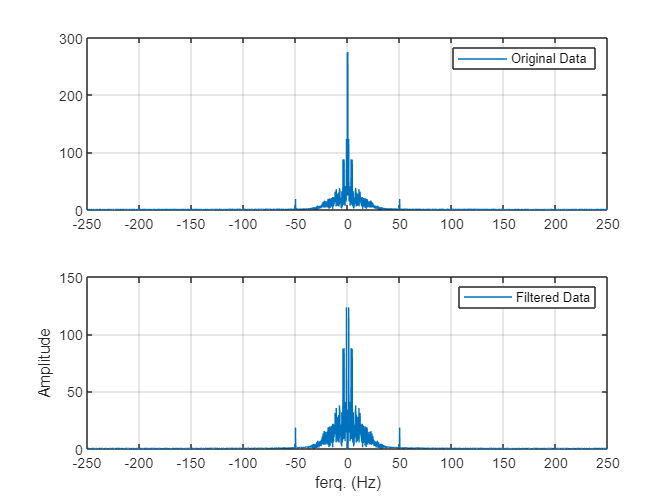


delta_f = 1/T_record;

freq = -fs/2:delta_f:fs/2-delta_f  ;

Signal_original_Freq = fftshift(fft(Signal_Original))' ;
% removing below 0.5 Hz
index_to_remove =   [ find(freq>=-0.5 & freq<=0.5)    ] ;
freq_filter_High_passed = [ ones(1,length(find(freq<-0.5))) , zeros(1,length(index_to_remove)) , ones(1,length(find(freq>0.5)))  ];
Impulse_res_Highpass   = ifft(freq_filter_High_passed);

Signal_Highpassed_Freq =  Signal_original_Freq.*freq_filter_High_passed  ;

ecg1 = ifft(fftshift(Signal_Highpassed_Freq));

figure()
subplot(2,1,1)
title("Original Signal VS Filtered using Highpass signal")
plot(freq, abs(Signal_original_Freq))
grid on
legend("Original Data")
subplot(2,1,2)
plot(freq,abs(Signal_Highpassed_Freq))
grid on
xlabel("ferq. (Hz)")
ylabel("Amplitude")
legend("Filtered Data")

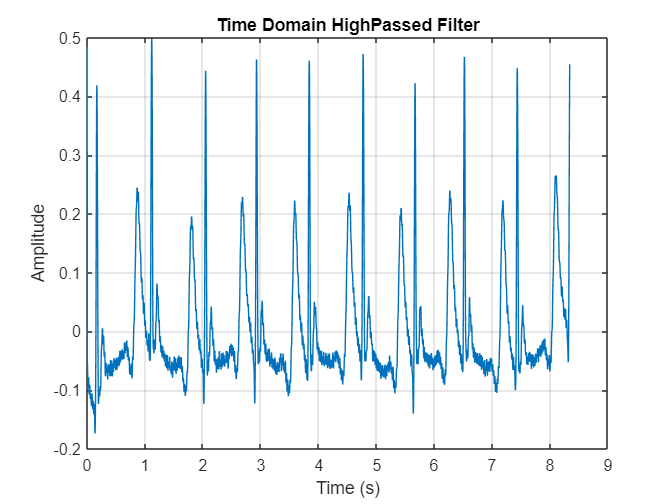

figure()
plot(t,ecg1)
title("Time Domain HighPassed Filter")
grid on
xlabel("Time (s)")
ylabel("Amplitude")

## Preprocessing: 1) Removing 50Hz

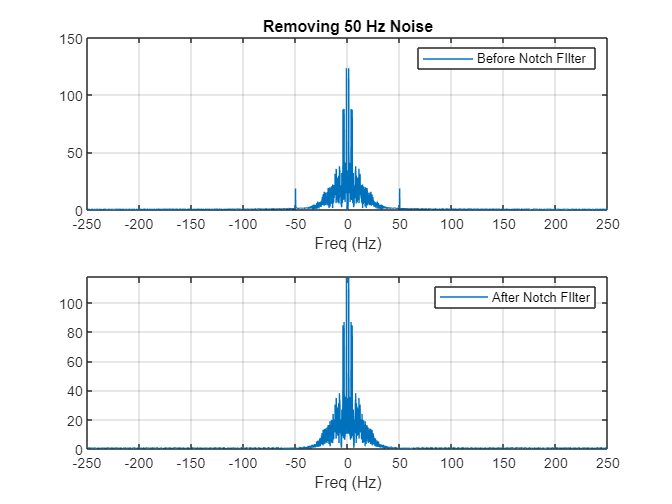



% Our Notch Filter:
Band_stop_filter = getFilter_Bandstop_3();

ecg2 = filter(Band_stop_filter,ecg1);

figure()
subplot(2,1,1)
plot(freq,abs(fftshift(fft(ecg1))));
title("Removing 50 Hz Noise")
grid on
xlabel("Freq (Hz)")
legend("Before Notch FIlter")
subplot(2,1,2)
plot(freq,abs(fftshift(fft(ecg2))));
grid on
legend("After Notch FIlter")
xlabel("Freq (Hz)")

## 3) <Preprocessing>  Increasing Signal to Noise Ratio:

Noise Power can be calculated using:


$$P_{n={{K\;T}_{0\;} B}_{n\;} }$$


where $K$ is the boltzmann constant which equals to 1.380649 × 10-23 m2 kg s-2 K-1, $T_0$ is the working temperature of the system and $B_{n\;}$is the equal Bandwidth of the noise. It is obvious that Noise Power is proportional to given Bandwidth. 

- The Lower the Bandwidth, the lower the Noise Power.

By designing 3 filters and choosing the best SNR with respect to data conservation we find the best filter and corresponding bandwidth.

Filter-1:    0.5-50Hz

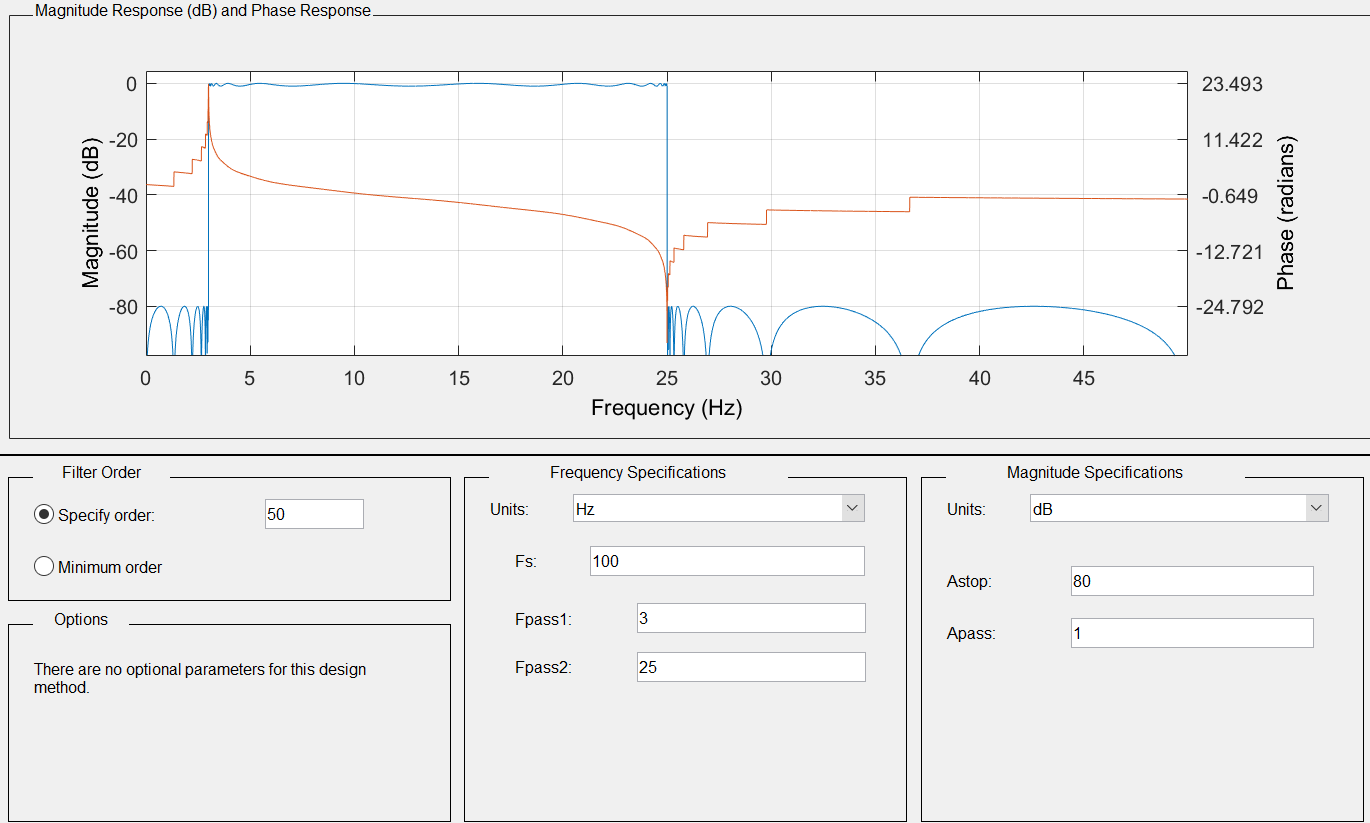 

Filter-2:    0.5-45Hz

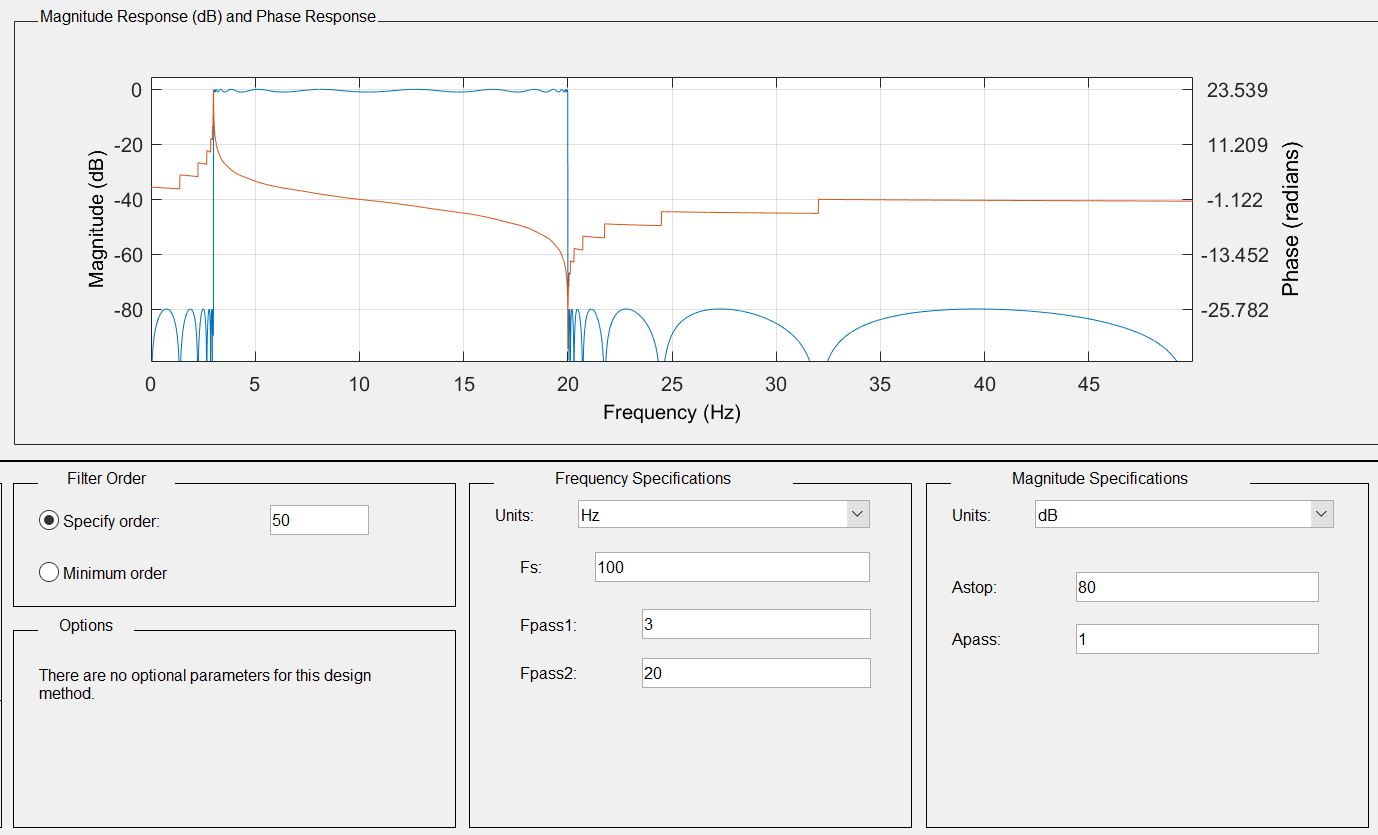

Filter-3:    0.5-40Hz

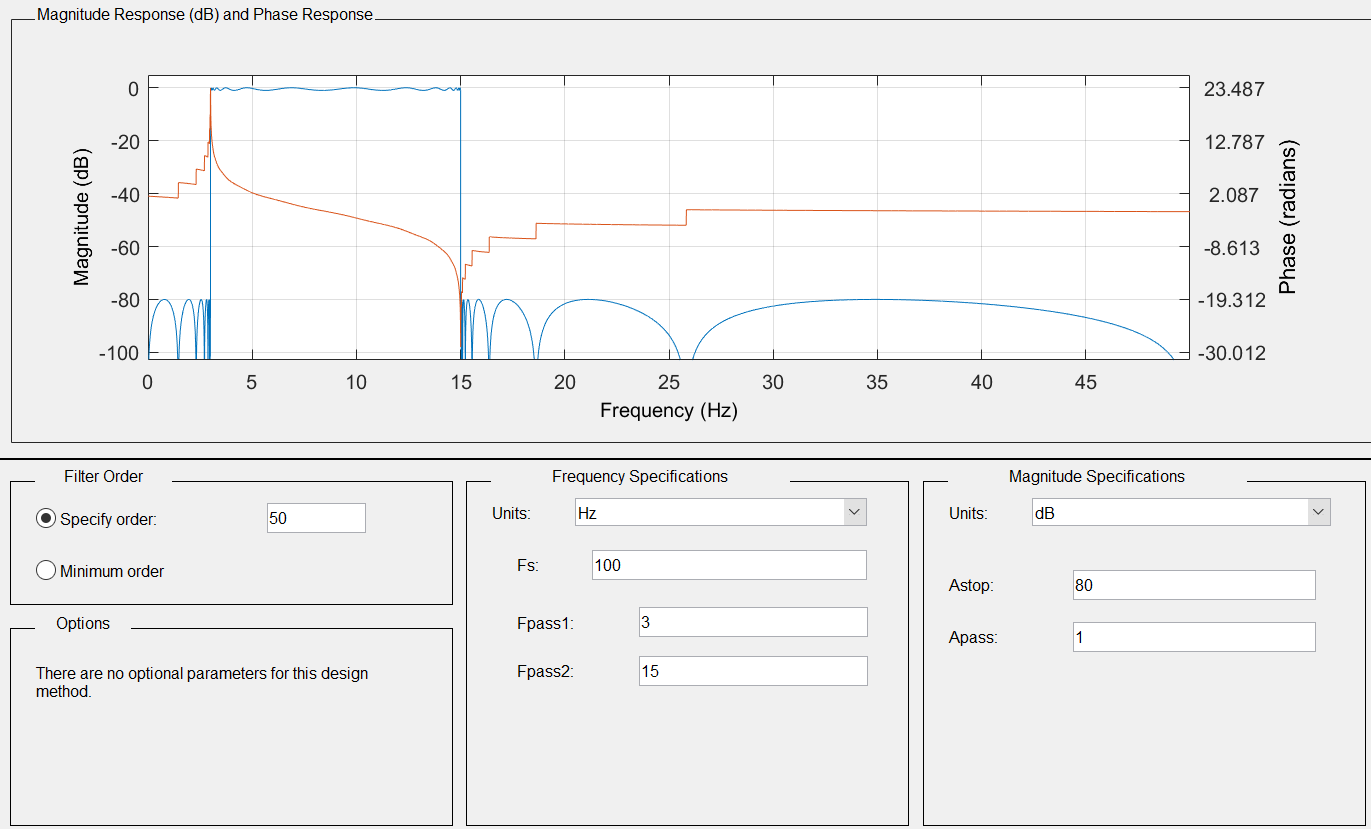

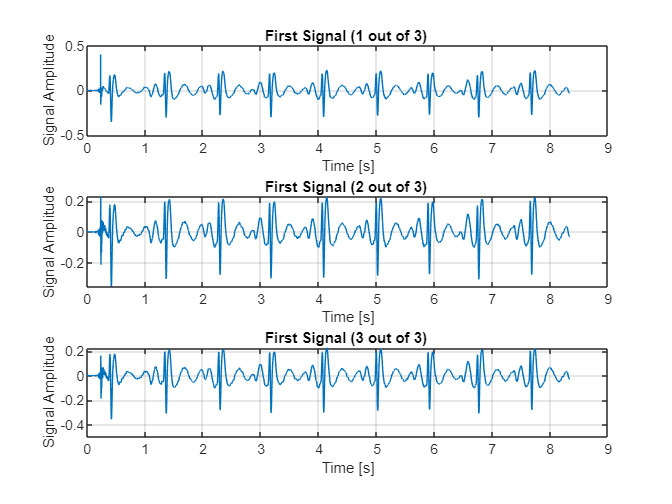

% Our BandPass Filter: <Noise Limitter> --> BandPass Filter to Reduce Noise
% Power:

Band_Pass_filter_1 = getFilter_BandPass_1();
Band_Pass_filter_2 = getFilter_BandPass_2();
Band_Pass_filter_3 = getFilter_BandPass_3();

ecg3_1 = filter(Band_Pass_filter_1,ecg2);
ecg3_2 = filter(Band_Pass_filter_2,ecg2);
ecg3_3 = filter(Band_Pass_filter_3,ecg2);

figure()
subplot(3,1,1)
plot(t,ecg3_1)
title("First Signal (1 out of 3) ")
xlabel("Time [s]")
ylabel("Signal Amplitude")
grid on

subplot(3,1,2)
plot(t,ecg3_2)
title("First Signal (2 out of 3) ")
xlabel("Time [s]")
ylabel("Signal Amplitude")
grid on

subplot(3,1,3)
plot(t,ecg3_3)
title("First Signal (3 out of 3) ")
xlabel("Time [s]")
ylabel("Signal Amplitude")
grid on

## Noise Calculation

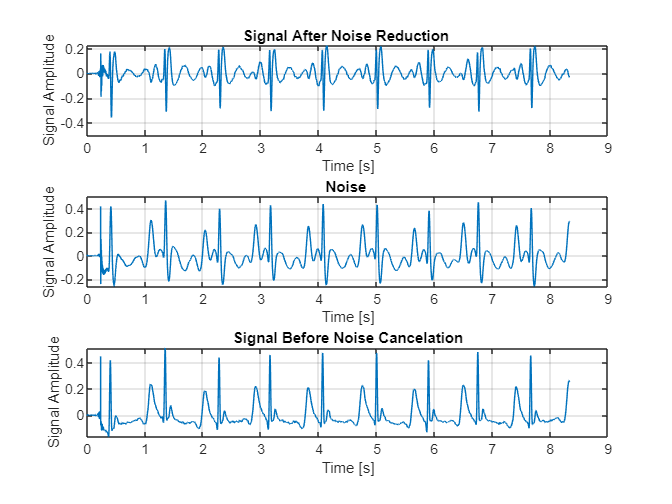



Noise_1 = ecg2-ecg3_1;
Noise_2 = ecg2-ecg3_2;
Noise_3 = ecg2-ecg3_3;


Noise_Power_1 =  sum(abs(Noise_1).^2);
Noise_Power_2 =  sum(abs(Noise_2).^2);
Noise_Power_3 =  sum(abs(Noise_3).^2);


[  min_val , min_idx] = min( [Noise_Power_1,Noise_Power_2,Noise_Power_3]  );
% Plotting the Noise and Coressponding Signal:

figure()
subplot(3,1,1)
plot(t,ecg3_3)
title(" Signal After Noise Reduction  ")
xlabel("Time [s]")
ylabel("Signal Amplitude")
grid on

subplot(3,1,2)
plot(t,Noise_3)
title("Noise ")
xlabel("Time [s]")
ylabel("Signal Amplitude")
grid on

subplot(3,1,3)
plot(t,ecg2)
title("Signal Before Noise Cancelation")
xlabel("Time [s]")
ylabel("Signal Amplitude")
grid on


Noise_canceled_power = sum(abs(ecg2).^2)  - Noise_Power_3 ;
disp("Reduced Noise Power: "+ 100*abs(Noise_canceled_power/sum(abs(ecg2))) + " %(Percentage)" );

Reduced Noise Power: 4.8535 %(Percentage)


SNR_New_lineaar = sum(abs(ecg3_1).^2  ) / (Noise_Power_3);
SNR_New_dB  =  10*log10(SNR_New_lineaar) ; 




## 4) Finding the Heart Rate Using Auto Correlation:

Trying ecg2 we have:

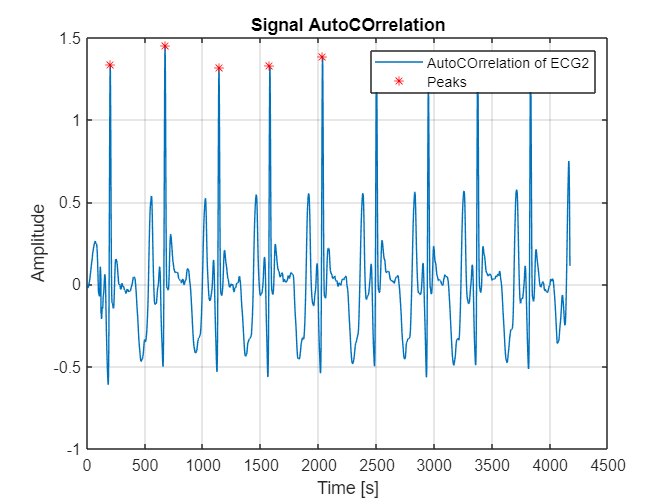



[Auto_COrr, lags ]= xcorr(ecg2,3*7*fs,'coeff');

[Auto_COrr2, lags2 ]= xcorr(ecg2, ecg2(2.28*fs:2.5*fs));

Mid = floor(length(Auto_COrr2)/2);
To_Check = Auto_COrr2(Mid:end);

To_Check(To_Check<0.8*max(max(To_Check))) =0;

[pks,locs] = findpeaks(To_Check);

RR_int = locs;

figure()
% subplot(2,1,1)
plot(Auto_COrr2(Mid:end))
hold on
plot(locs,pks ,'r*')
grid on
xlabel("Time [s]")
ylabel("Amplitude")
legend("AutoCOrrelation of ECG2" , "Peaks")
title("Signal AutoCOrrelation")

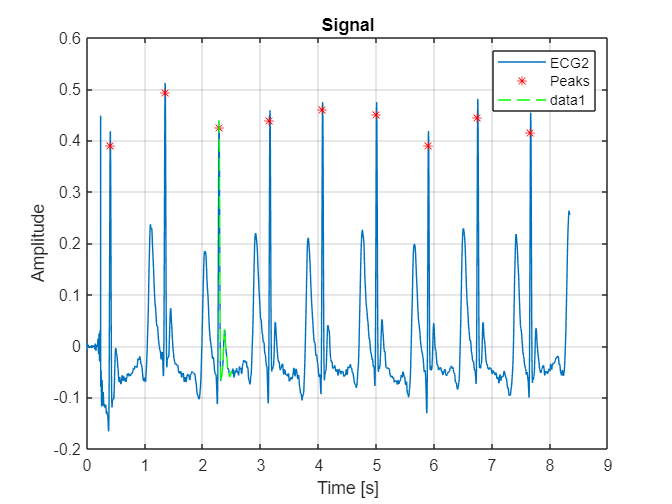


figure()
plot(t,ecg2)
hold on
plot(locs/fs,ecg2(locs) ,'r*')
grid on
xlabel("Time [s]")
ylabel("Amplitude")
legend("ECG2" , "Peaks")
title("Signal")

hold on 
plot(t(2.28*fs:2.5*fs),ecg2(2.28*fs:2.5*fs),'g--')
hold off

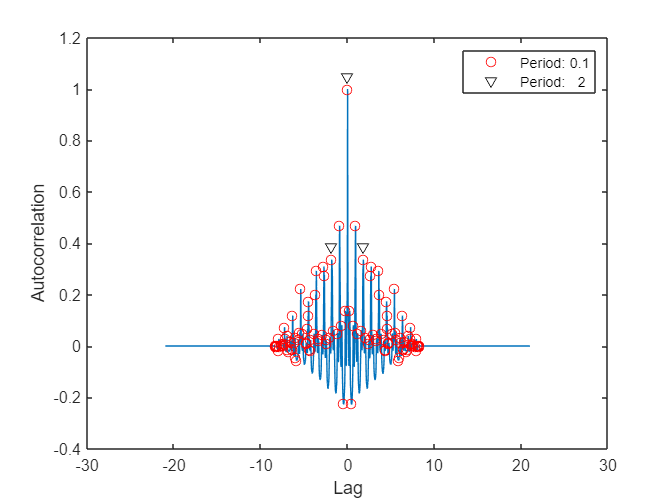



close all
figure()
plot(lags/fs,Auto_COrr)
xlabel('Lag')
ylabel('Autocorrelation')
hold on
[pksh,lcsh] = findpeaks(Auto_COrr);
short = mean(diff(lcsh))/fs;

[pklg,lclg] = findpeaks(Auto_COrr, ...
    'MinPeakDistance',ceil(short)*fs,'MinPeakheight',0.3);
long = mean(diff(lclg))/fs;
pks = plot(lags(lcsh)/fs,pksh,'or', ...
    lags(lclg)/fs,pklg+0.05,'vk');


legend(pks,[repmat('Period: ',[2 1]) num2str([short;long],0)]);
hold off